J=0.0006399

J = 6.3990e-04

B=0.0169

B = 0.0169

K=362

K = 362

%tau=0.05
k_e=10

k_e = 10

b_e=3

b_e = 3

m_e=1

m_e = 1

P_m=10

P_m = 10

I_m=2000

I_m = 2000

eval(aa1)

ans = 	1.0e+12 *

    1.5727
    0.0000
    0.0000


eval(routh)

ans = 	1.0e+05 *

    0.0000    0.0239    7.4762
    0.0001    0.1081         0
    0.0239    7.4762         0
    0.0767         0         0
    7.4762         0         0


eval(beta)

ans = -8.2520e+18

eval(K_min)

ans = 2.8660e+04

((- B^2 + 4*b_e*B + 4*P_m*b_e))

ans = 120.2025

syms s;
x=s

$$x = s$$

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf(numa,[dena 0]);
%Z=tf([1 20 100],[100 0])
w = logspace(-2,2,20)

w =     0.0100    0.0162    0.0264    0.0428    0.0695    0.1129    0.1833    0.2976    0.4833    0.7848    1.2743    2.0691    3.3598    5.4556    8.8587   14.3845   23.3572   37.9269   61.5848  100.0000


[re,im,freq] = nyquist(sys,w);
syms w
syms(w,'real');
s=j*w

$$s = w\,\mathrm{i}$$

%Z2=(s^2+20*s+100)/(100*s)
%Z2=eval(Z2)
im_pos_index=find(( im>0 ))

im_pos_index =     13
    14
    15
    16


im_neg_index=find(( im<0 ))

im_neg_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


re_pos_index=find(( re>0 ))

re_pos_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ES=[]


ES =

     []



EM=[]


EM =

     []



ED=[]


ED =

     []



a=1

a = 1

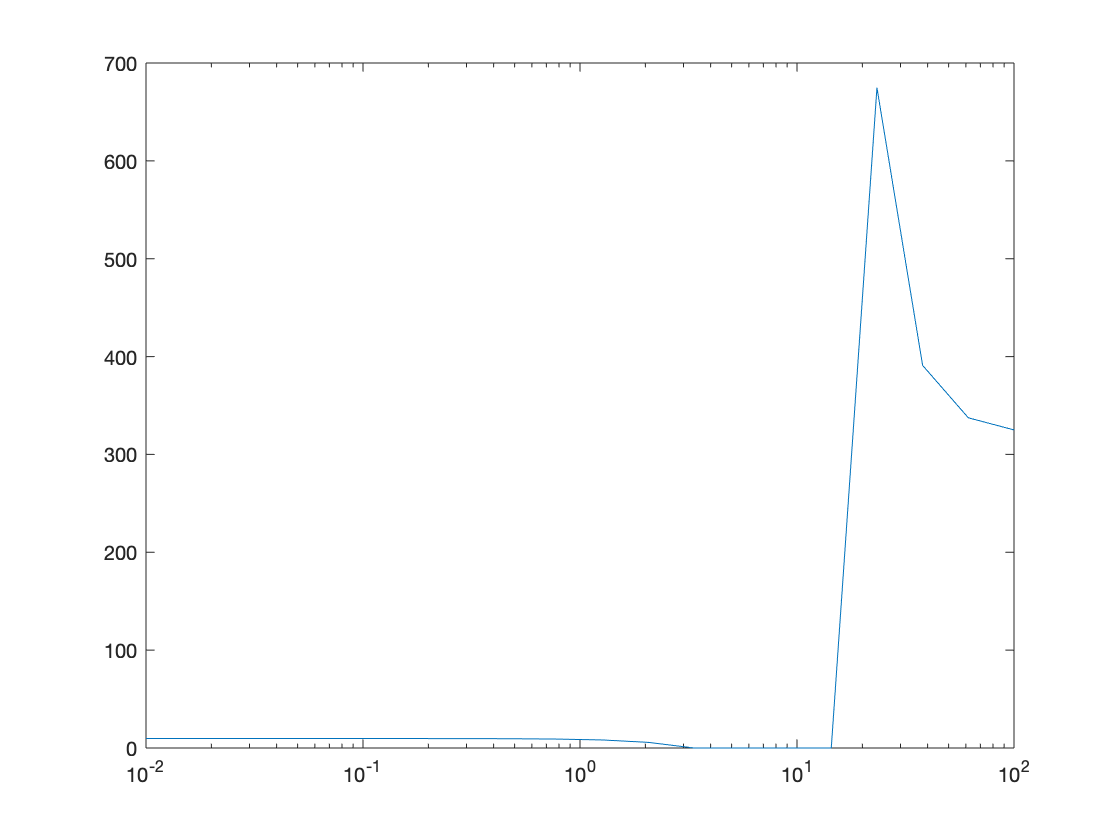

for i=1:length(freq)
    if any(im_neg_index==i)
    ES(i)=-freq(i)*im(:,:,i);
    else
    ES(i)=0;
    end
end
for i=1:length(freq)
    if any(im_pos_index==i)
    EM(i)=freq(i)^-1*im(:,:,i);
    else
    EM(i)=0;
    end
end
for i=1:length(freq)
    if any(re_pos_index==i)
    ED(i)=re(:,:,i);
    else
    ED(i)=0;
    end
end
plot(freq,ES)
set(gca, 'XScale', 'log')

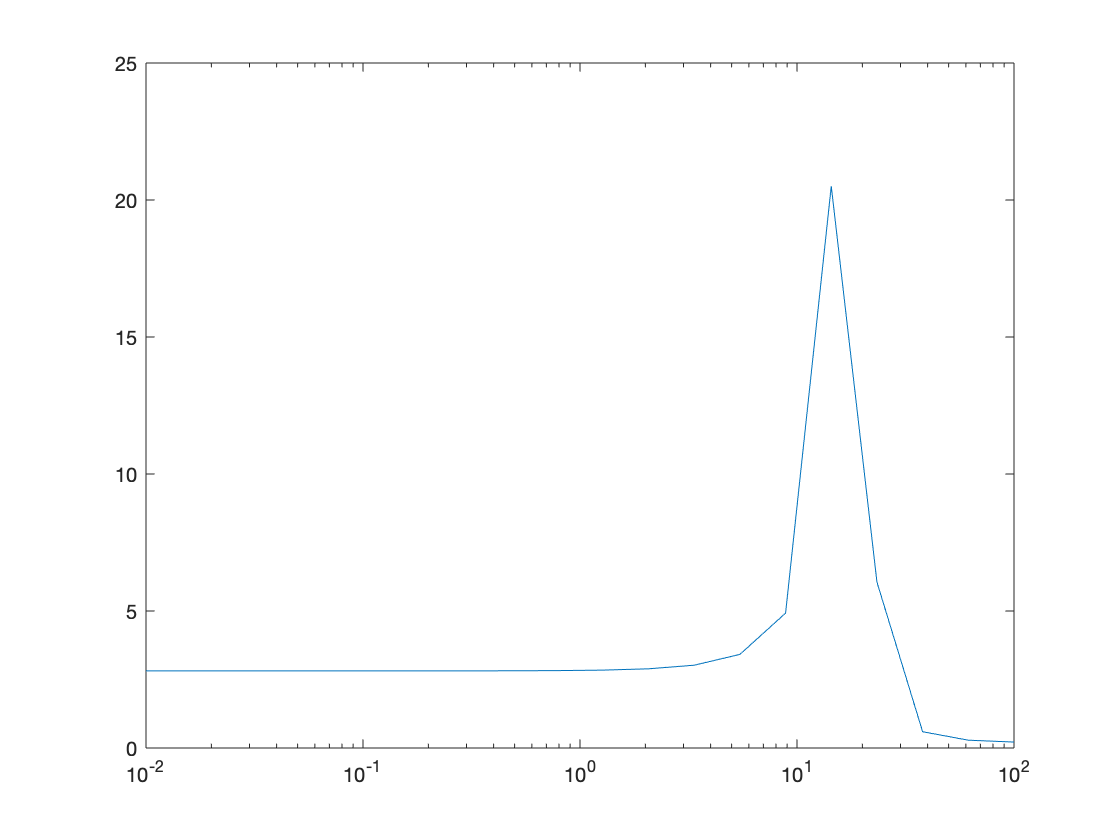

plot(freq,ED)
set(gca, 'XScale', 'log')

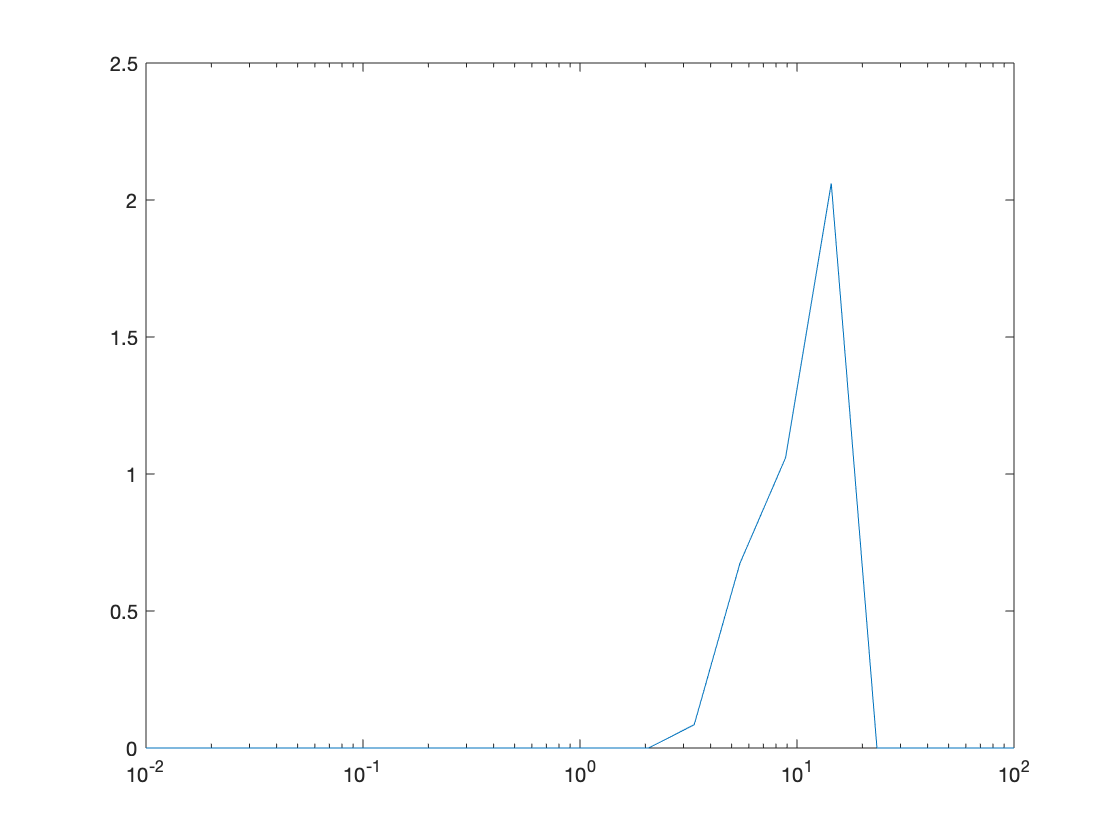

plot(freq,EM)
set(gca, 'XScale', 'log')

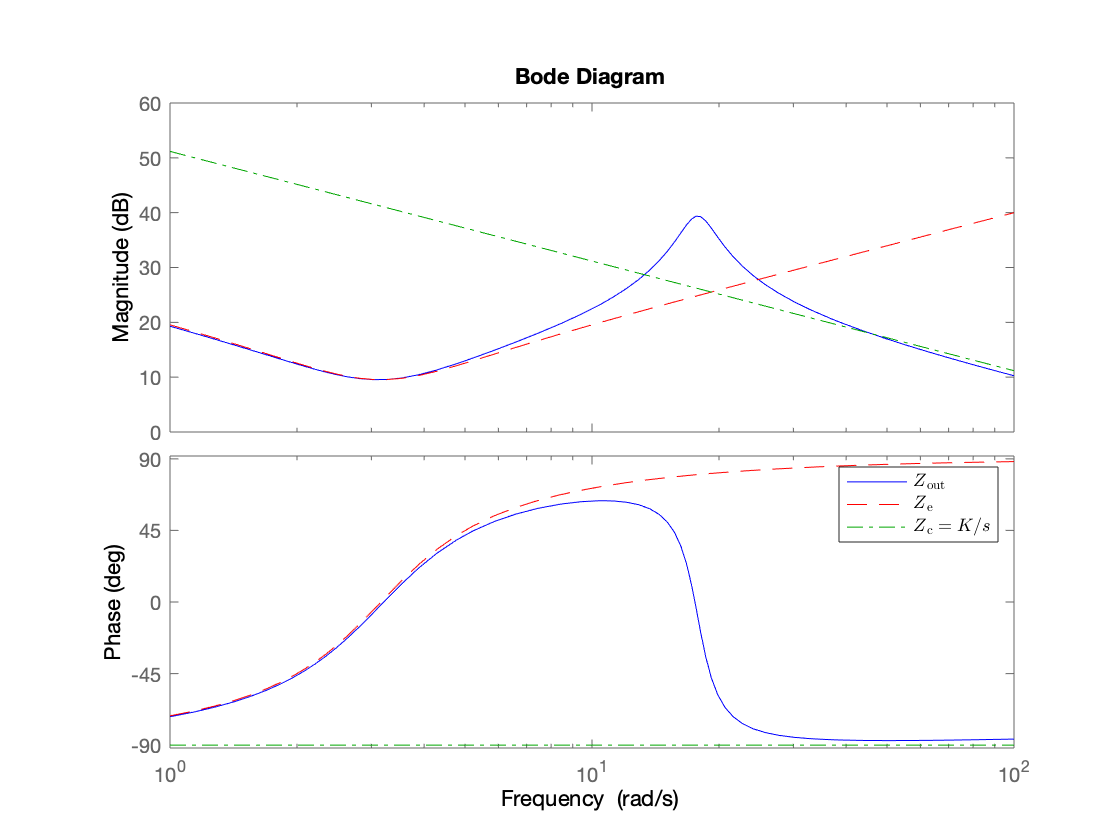

clear s; syms s
phy=tf([K],[1, 0]);
[nume dene]=numden((Y_e));
dene=eval(fliplr(coeffs(dene,s)));
nume=eval(fliplr(coeffs(nume,s)));
env=tf(dene,[1 0]);

% Normal below
bode(sys,'b-',env,'r--',phy,'g-.',{1,100}) 
h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{e}}$', '$Z\_{\mathrm{c}}=K/s$'); set(h, 'Interpreter', 'latex');